 And do you have a way of converting from range bin to depth? Finally (and related), can you estimate how deep the ice is at this lat/long?

addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_standard\20240105_02\
addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layer\20240105_02\
addpath C:\Users\macaw\Documents\scripts\matlab\functions

load Data_img_01_20240105_02_005.mat
load Data_20240105_02_005.mat

%generateEchogram


depth = twtt2Depth(twtt, 1.77);

depth = 1.0e+03 *

    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3424    0.3429    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430
    2.6344    2.6347    2.6333    2.6301    2.6275    2.6270    2.6274    2.6282    2.6286    2.6287    2.6293    2.6303    2.6319    2.6336    2.6347    2.6353    2.6355    2.6347    2.6330    2.6301    2.6265    2.6247    2.6237    2.6221    2.6200    2.6174    2.6147    2.6119    2.6095    2.6076    2.6063    2.6053    2.6056    2.6067    2.6098    2.6138    2.6191    2.6226    2.6225    2.6216    2.6207    2.6197    2.6188    2.6159    2.6124    2.6102    2.6087    2.6084

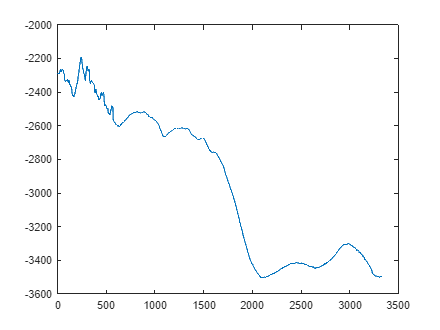


realBottomDepth = depth;
bottomDepth = realBottomDepth(2, :) - realBottomDepth(1, :);

x = linspace(0, size(bottomDepth,2), size(bottomDepth, 2));

hold off
plot(x, -bottomDepth)

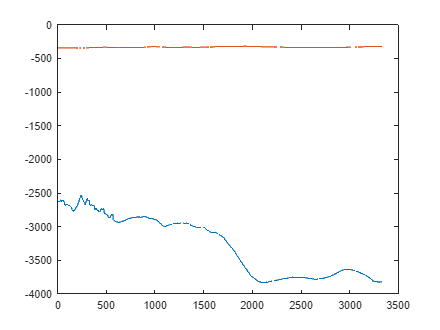

title('raw data')

plot(x, -realBottomDepth(2, :))
hold on
plot(x, -realBottomDepth(1, :))

title('actual bottom depth')
